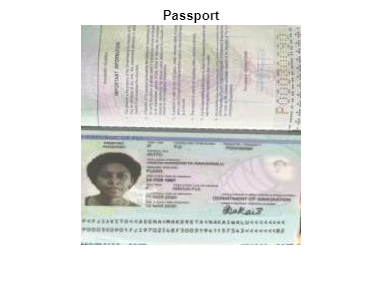

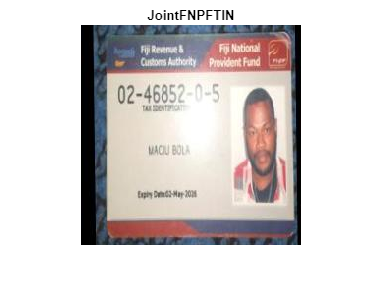

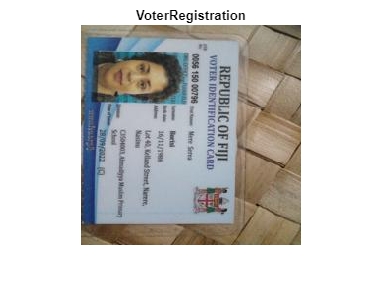

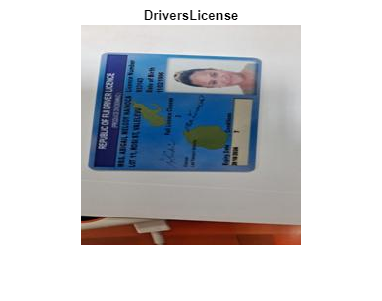

tic;
load('TrainedOverSampledFijiIDCardClassifier.mat', 'netTransfer');

% Define the folder containing your test image dataset


% Load the test dataset
imdsTest = imageDatastore('IDDataOverSampleTest', 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Get the input size of the network
inputSize = netTransfer.Layers(1).InputSize;

% Resize the test images to match the input size of the network
augimdsTest = augmentedImageDatastore(inputSize(1:2), imdsTest);

% Classify the test images
[YPred, scores] = classify(netTransfer, augimdsTest);

% Display some example results
idx = randperm(numel(imdsTest.Files), 4);
for i = 1:4
    figure;
    imshow(imdsTest.Files{idx(i)});
    title(string(YPred(idx(i))));
end


% Get the actual labels (if available)
YTest = imdsTest.Labels;

% Calculate the accuracy (if labels are available)
if ~isempty(YTest)
    accuracy = mean(YPred == YTest);
    disp(['Test accuracy: ', num2str(accuracy)]);
end

Test accuracy: 0.99786


%imdsTest.Files(YPred ~= YTest)
ConfusionMatrix = confusionmat(YTest,YPred)

ConfusionMatrix =    933     0     1     0
     0   933     0     1
     0     0   934     0
     2     1     3   928


toc;

Elapsed time is 40.582725 seconds.
